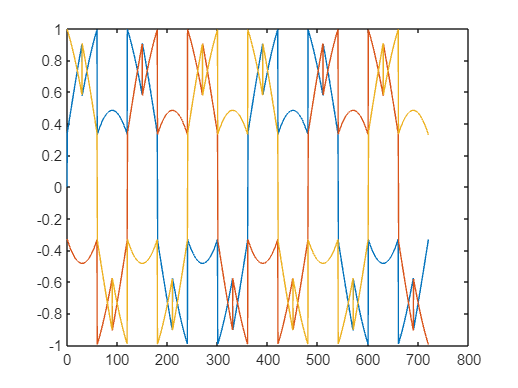

f = 50;
ma =1.15;
t= linspace(0,720,1800);
ua =1/3*(t>0)-1/3*(t>=30)-2/3*(t>=60)+2/3*(t>=120)+1/3*(t>=150)-1/3*(t>=180);
ua = ua-circshift(ua,length(t)/4)+circshift(ua,length(t)/2)-circshift(ua,3*length(t)/4);
a = ma*sin(2*pi*t/360)+ua;
ub=circshift(ua,length(t)/6);
uc=circshift(ua,-length(t)/6);
b = ma*sin(2*pi*(t-120)/360)+ub;
c = ma*sin(2*pi*(t+120)/360)+uc;
plot(t,a,t,b,t,c)

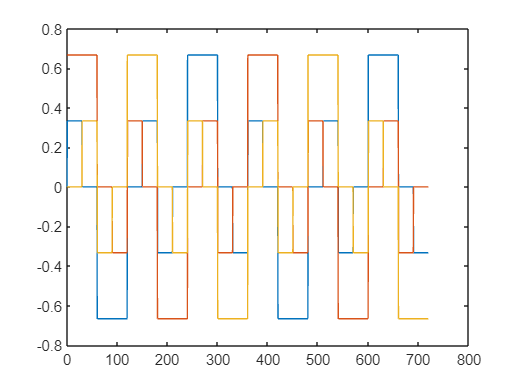

plot(t,ua,t,ub,t,uc)

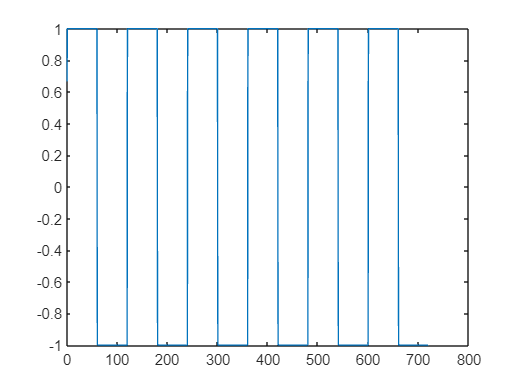

plot(t, ua+ub+uc)


L = 1800;             % Length of signal
t=t/720/50; % angle to time
Fs=1/(t(2)-t(1)) % sampling frequency

Fs = 89950

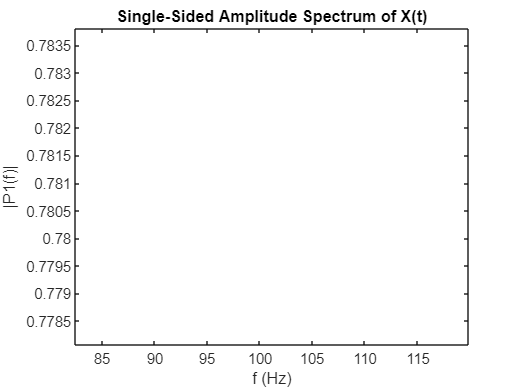



Y = fft(a);

P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = Fs/L*(0:(L/2));
plot(f,P1,"LineWidth",3) 
% xlim([0 1e5])
title("Single-Sided Amplitude Spectrum of X(t)")
xlabel("f (Hz)")
ylabel("|P1(f)|")